## **Denoising **

signal with noise model : $y=x+w$

where $x\in R^{n\;}$is the noise_free signal, $w\in R^n \;$is the noise vector, and $y\in R^{n\;}$is thee observed and known vector. 

first solution is:

                                                   
$$\mathrm{min}\;\left|\right|x-y\left|{\left|\right.}^2 +\lambda \right|\left|\mathrm{Lx}\right|{\left|\right.}^2 ,$$


where

                                          
$$L=\left\lbrack \begin{array}{ccccccc}
1 & -1 & 0 & 0 & 0 & \ldotp \ldotp \ldotp  & 0\\
0 & 1 & -1 & 0 & 0 & \ldotp \ldotp \ldotp  & 0\\
0 & 0 & 1 & -1 & 0 & \ldotp \ldotp \ldotp  & 0\\
0 & 0 & 0 & 1 & -1 & \ldotp \ldotp \ldotp  & 0\\
\vdots  & \vdots  & \vdots  & \vdots  & \vdots  & \vdots  & \vdots \\
0 & 0 & 0 & 0 & \ldotp \ldotp \ldotp  & 1 & -1
\end{array}\right\rbrack$$


this problem is regularized LS problem, and its optimal solution can be derived by writing the stationary condition

                                                     
$$2\left(x-y\right)+2\lambda L^T \textrm{Lx}=0\ldotp$$


thus, 

                                                        $x={{\left(I+\lambda L^T L\right)}^{-1} y}_{\ldotp }$    (1)

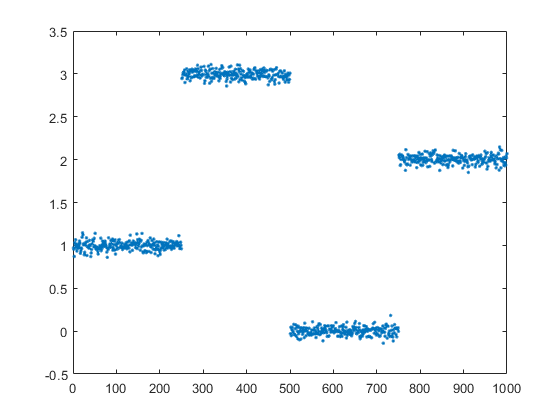

randn('seed', 314);
x = zeros(1000,1);
x(1:250) = 1;
x(251:500) = 3;
x(501:750) = 0;
x(751:1000) = 2;
y = x+0.05*randn(size(x));
figure(1)
plot(1:1000,y,'.')

so based on 1 we have:

Define $L\;$as below :

L = sparse(999,1000);
for i=1:999
    L(i,i)=1;
    L(i,i+1)=-1;
end

$\lambda =0\ldotp 1$:

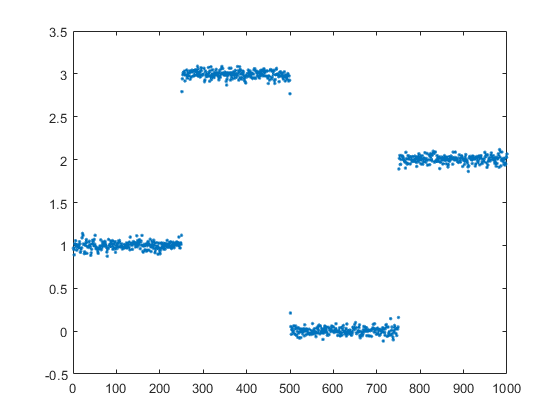

lambda=0.1;
xde=(speye(1000)+lambda*L'*L)\y;
figure(2)
plot([1:1000],xde,'.');

$\lambda =10$:

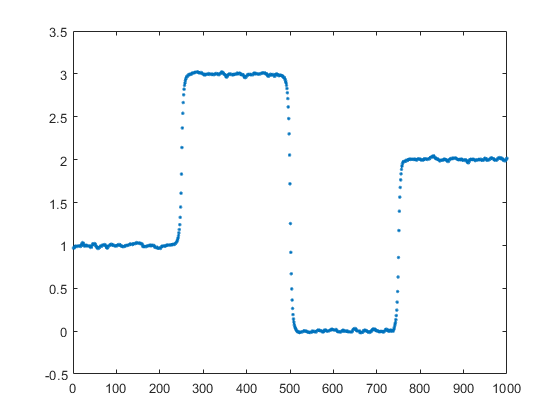

lambda=10;
xde=(speye(1000)+lambda*L'*L)\y;
figure(3)
plot([1:1000],xde,'.');

$\lambda =100$:

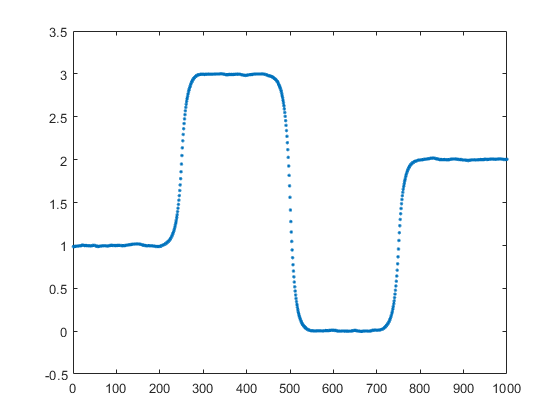

lambda=100;
xde=(speye(1000)+lambda*L'*L)\y;
figure(4)
plot([1:1000],xde,'.');

this plots shows that the regularized least squars solution isn't a good reconstruction since it is unable to deal correctly with breakpoints. The reason is that the jumps contribute large values to penalty function $\left|\right|\textrm{Lx}\left|{\left|\right.}^2 \right.$ since their values are squared. Therefore, in a sense the RLS solution tries to "smooth" the jumps. 

let solve this issue as below with dowindeling the effect of $\left|\right|\mathrm{Lx}\left||\right.$ for avoiding  smoothing the jumps:

                                                                                    
$$\min \;\left|\right|x-y\left|{\left|\right.}^2 +\lambda \right|\left|\textrm{Lx}\right|{\left|\right.}_1 ,$$


The problem is equivalent to the optimization problem

                                                                                    
$$\begin{array}{l}
\mathrm{min}\;\left|\right|x-y\left|{\left|\right.}^2 +\lambda \right|\left|z\right|{\left|\right.}_1 \\
s\ldotp t\ldotp \;\;\;\;\;\;\;\;\;z=\mathrm{Lx}\ldotp 
\end{array}$$


The Lagrangian of the problem is:

                                                                                    
$$L\left(x,z,\mu \right)=||x-y||^2 +\lambda ||z||_1 +\mu^T \left(\mathrm{Lx}-z\right)=||x-y||^2 +{\left(L^T \mu \right)}^T x+\lambda ||z||_1 -\mu^T z\ldotp$$
 

to conclude the dual objective function is given by 

                                                                                    
$$q\left(\mu \right)=\underset{x,z}{\mathrm{min}} \;L\left(x,z,\mu \right)=\left\lbrace \begin{array}{cc}
-\frac{1}{4}\mu^T {\mathrm{LL}}^T \mu +\mu^T \mathrm{Ly} & ||\mu ||_{\infty } \le \lambda ,\\
-\infty  & \mathrm{else}\ldotp 
\end{array}\right.$$


Therefore, the dual problem is

                                                                                    $\begin{array}{l}
\mathrm{max}\;\;\;\;\;\;\;\;\;-\frac{1}{4}\mu^T {\mathrm{LL}}^T \mu +\mu^T \mathrm{Ly}\\
s\ldotp t\ldotp \;\;\;\;\;\;\;\;\;\;||\mu ||_{\infty } \le \lambda 
\end{array}$             (2)

based on Lipschitz constant

                                                                                    
$$\lambda_{\mathrm{max}} \left({\mathrm{LL}}^T \right)=\lambda_{\mathrm{max}} \left(L^T L\right)\le 4\ldotp$$


if we employ the gradient projection method on problem (2) with constant stepsize $\frac{1}{2}$, the method will read as

                                                                                     
$$\mu_{k+1} =P_c \left(\mu_k -\frac{1}{4}{\mathrm{LL}}^T \mu_k +\frac{1}{2}\mathrm{Ly}\right),$$


where

                                                                                    
$$C=\left\lbrace z\in R^{n-1} :-\lambda \le z_i \le \lambda ,i=1,2\ldotp \ldotp \ldotp ,n-1\right\rbrace \ldotp$$


if the result of the gradient projection method is $\mu^*$, the promal optimal solution will be $x^* =y-\frac{1}{2}L^T \mu^* \ldotp$

randn('seed', 314);
x = zeros(1000,1);
x(1:250) = 1;
x(251:500) = 3;
x(501:750) = 0;
x(751:1000) = 2;
y = x+0.05*randn(size(x));
figure(5)
plot(1:1000,y,'.')

based on top solution method we have:

Define $L\;$as below:

L = sparse(999,1000);
for i=1:999
    L(i,i)=1;
    L(i,i+1)=-1;
end

$\lambda =0\ldotp 1$:

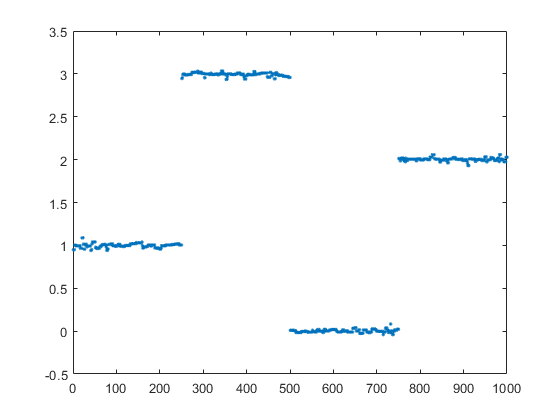

lambda = 0.1;
mu = zeros(999,1);
for i=1:1000
    mu=mu-0.25*L*(L'*mu)+0.5*(L*y);
    mu=lambda*mu./max(abs(mu),lambda);
    xde=y-0.5*L'*mu;
end
figure(6)
plot([1:1000],xde,'.');

$\lambda =1$:

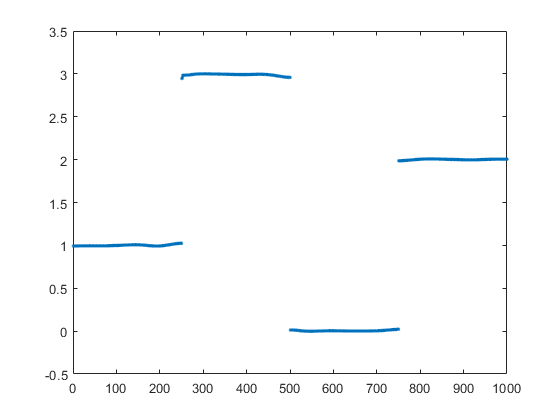

lambda = 1;
mu = zeros(999,1);
for i=1:1000
    mu=mu-0.25*L*(L'*mu)+0.5*(L*y);
    mu=lambda*mu./max(abs(mu),lambda);
    xde=y-0.5*L'*mu;
end
figure(6)
plot([1:1000],xde,'.');

$\lambda =10$:

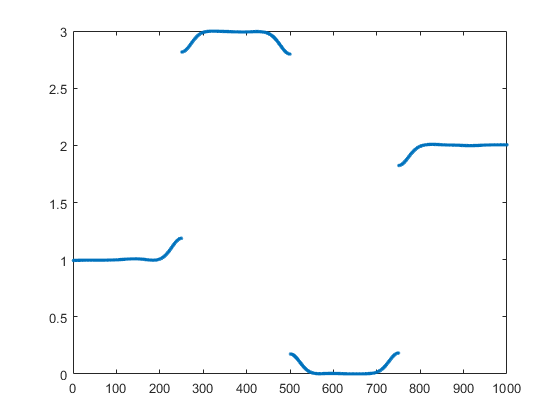

lambda = 10;
mu = zeros(999,1);
for i=1:1000
    mu=mu-0.25*L*(L'*mu)+0.5*(L*y);
    mu=lambda*mu./max(abs(mu),lambda);
    xde=y-0.5*L'*mu;
end
figure(6)
plot([1:1000],xde,'.');

$\lambda =100$:

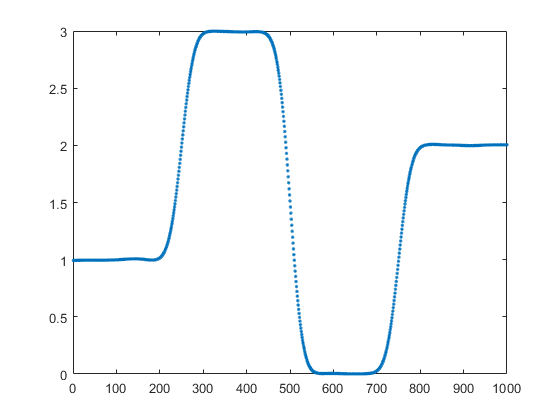

lambda = 100;
mu = zeros(999,1);
for i=1:1000
    mu=mu-0.25*L*(L'*mu)+0.5*(L*y);
    mu=lambda*mu./max(abs(mu),lambda);
    xde=y-0.5*L'*mu;
end
figure(6)
plot([1:1000],xde,'.');